clear;

U = [0,0,0,0.5,1,1,1]; % 7 - 3 = 4
V = [0,0,0,1,1,1]; % 6 - 3 = 3
Q(:,:,1) = [0,0,0;
    3,0,3;
    6,0,3;
    9,0,0];
Q(:,:,2) = [0,2,2;
    3,2,5;
    6,2,5;
    9,2,2];
Q(:,:,3) = [0,4,0;
    3,4,3;
    6,4,3;
    9,4,0];
Q = permute(Q,[3,1,2]);

sp = spmak({U,V},Q);
fnplt(sp);
hold on

sp_u = fnder(sp,[1,0]);
sp_v = fnder(sp,[0,1]);

u = 0.24;
v =  0.64;

pt = fnval(sp,{u,v})

pt =     1.2250
    2.9658
    3.0682


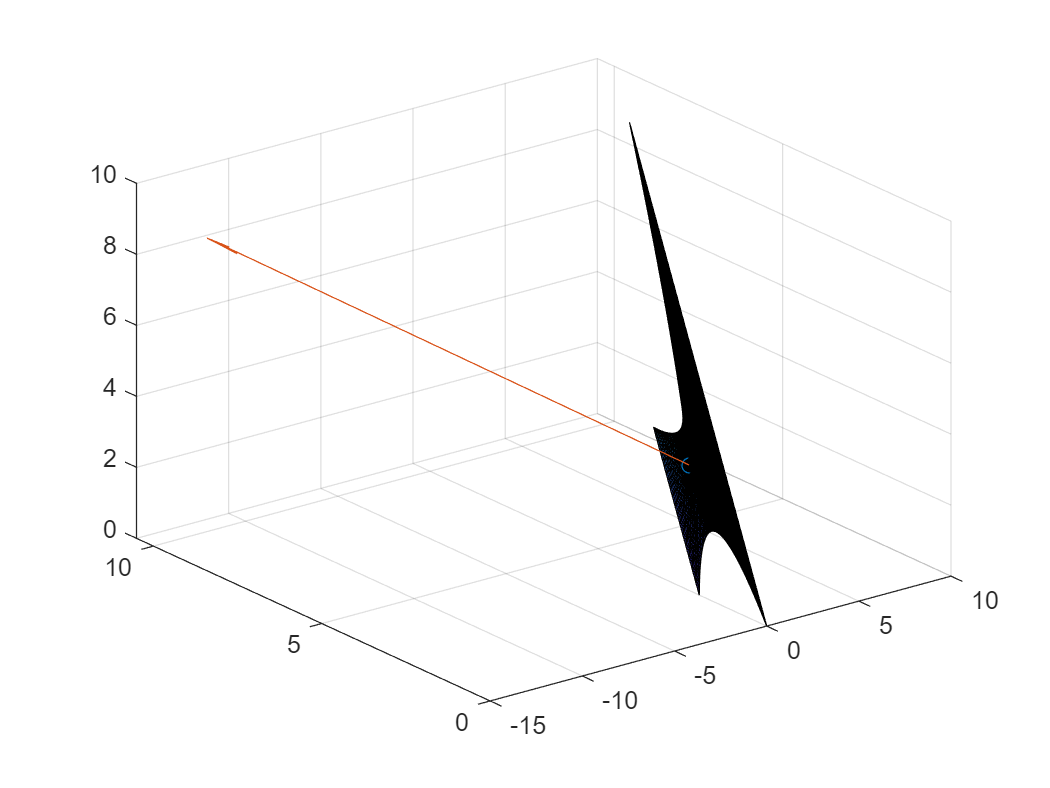

u_vec = fnval(sp_u,{u,v});
v_vec = fnval(sp_v,{u,v});
norm_vec = cross(u_vec,v_vec);
scatter3(pt(1),pt(2),pt(3));
quiver3(pt(1),pt(2),pt(3),norm_vec(1),norm_vec(2),norm_vec(3));
hold off;